clc;clearvars;close all;
global DOFS;
DOFS = [true,true,false];
L = 1;
E = 100;
A = 1;
p = 1;
h = L*sind(60);

## Defining Nodes


n1 = NODES(1, L/2  , h, fx=p, fy=-2*p);
n2 = NODES(2, 1.5*L, h, constraint = "hroller");
n3 = NODES(3, 0    , 0, constraint = "simple" );
n4 = NODES(4, L    , 0, constraint = "simple" , dx = 0.04*L);

## Defining Cross sections

cr = tempcross(E,A);

## Defining Members

m1 = member(n1,n2,cr);
m2 = member(n3,n4,cr);
m3 = member(n3,n1,cr);
m4 = member(n1,n4,cr);
m5 = member(n4,n2,cr);

## Defining Loads

L1 = n_tri(m1,0,L,6*p/L,"down","g");
L2 = con_fm(m2,0.5*m2.L,2*p,"up","g");
L5 = con_fm(m5,0.5*m5.L,2*p,"down","g");

## Automatically creating the cell matrices and running the final solver

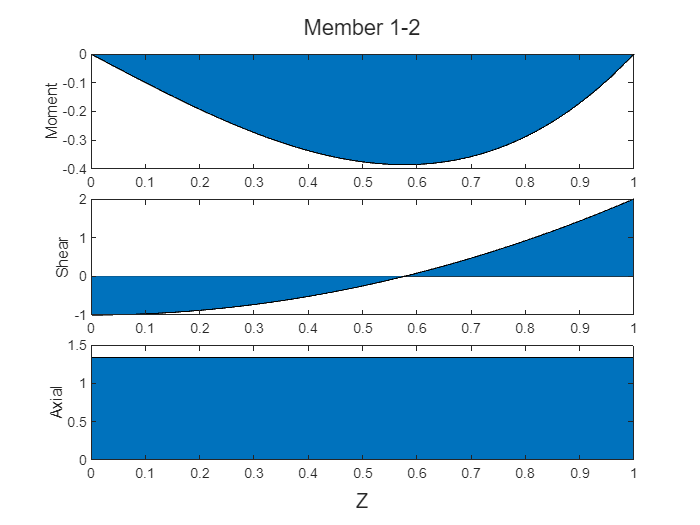

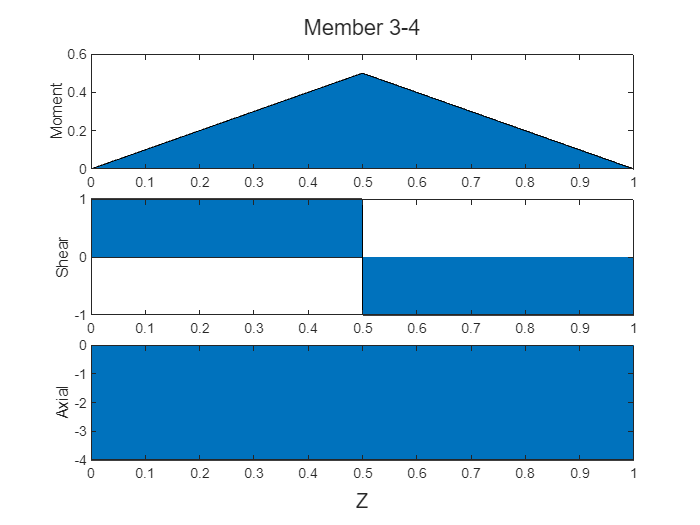

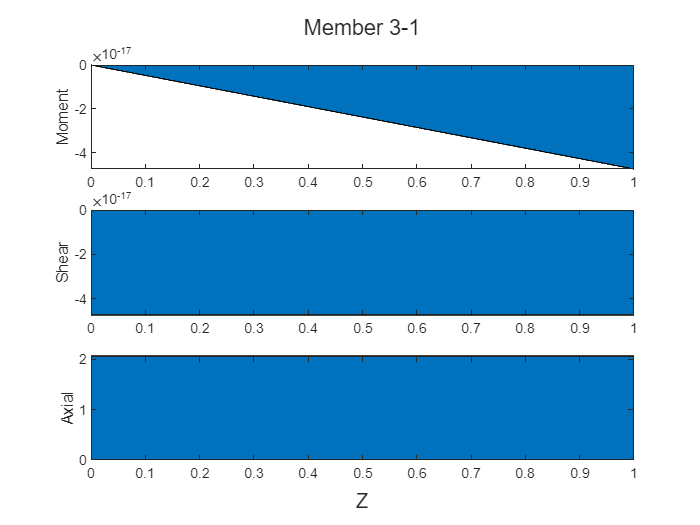

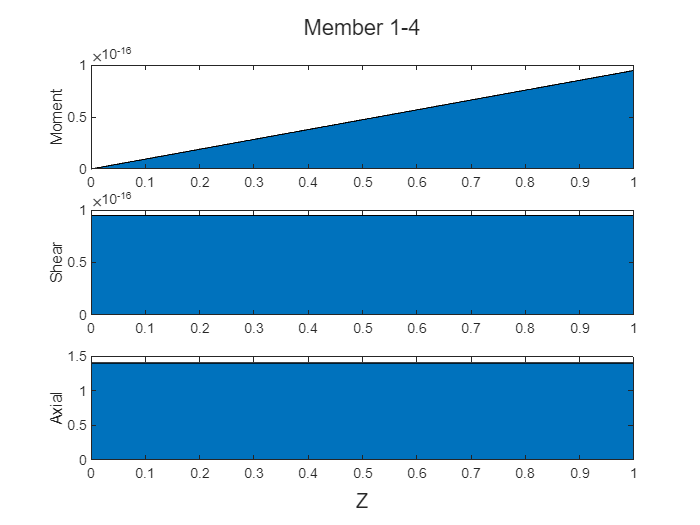

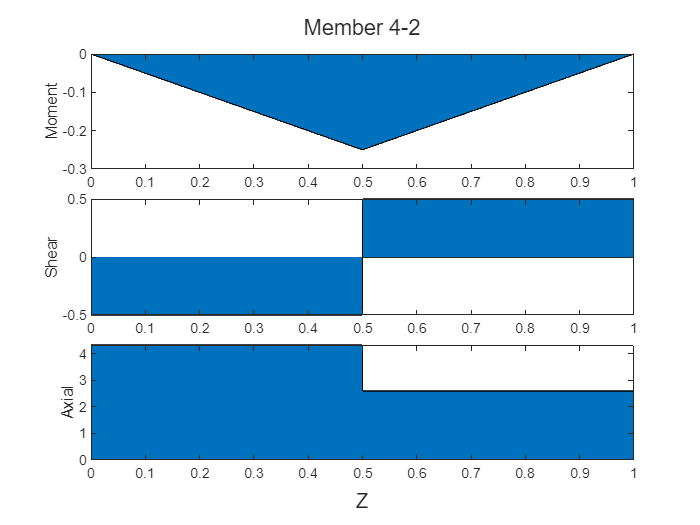

Deflections:
    0.0133
   -0.0315
   -0.0169

Reactions:
   -3.0654
   -2.9673
    0.7887
    5.0327
    4.2113



members = {};
nodes = {};
loads = {};
j = evalin('base','who');
for n = 1:length(j)
    r = evalin('base',j{n});
    if isa(r,'member')
        members = {members{:},r};
    elseif isa(r,'NODES')
        nodes = {nodes{:},r};
    elseif isa(r,'con_fm')||isa(r,'con_m')||isa(r,'n_tri')||isa(r,'rec')||isa(r,'rev_tri')
        loads = {loads{:},r};
    end
end
[Ar,D,Df,members] = final_solver(members,nodes,loads);